# Harnessing Electric Fields for Sustainable Solar Panel Cleaning in the Sahara

In the harsh conditions of the Sahara Desert, maintaining the efficiency of solar panels is a persistent challenge due to the accumulation of sand and dust. Existing cleaning methods often involve substantial water consumption and logistical complexities in transporting water to the remote desert. This computational modeling introduces a novel solution—utilizing an electric field for solar panel cleaning. By minimizing water usage and optimizing the cleaning process, this approach aims to enhance the sustainability and efficiency of solar power generation in the challenging Sahara environment.

# Computational modeling of the solution

We establish the frame of reference

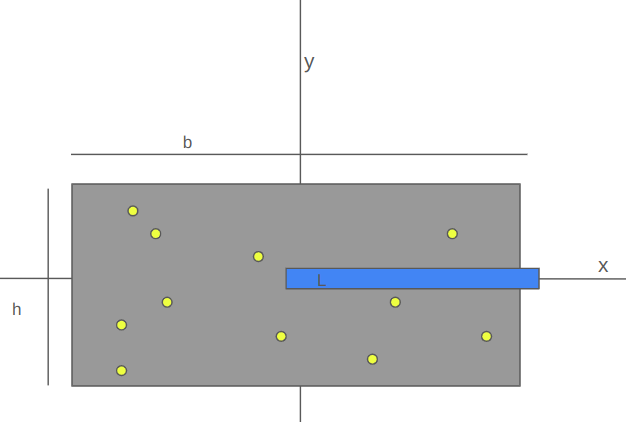

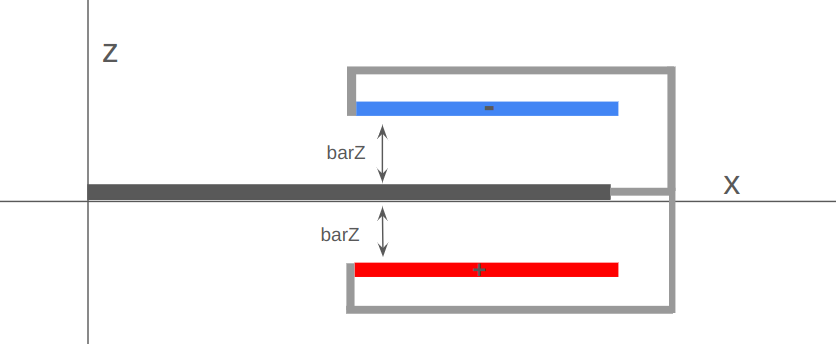

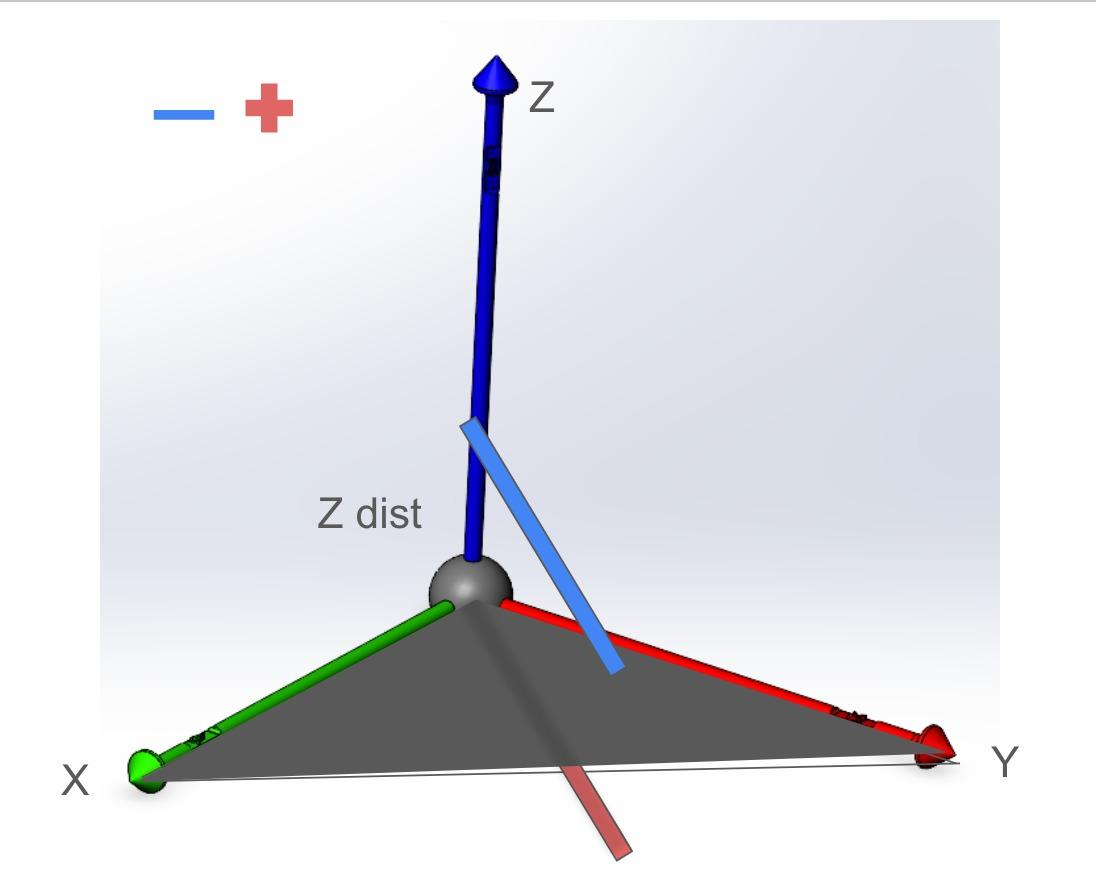

We then declare some variables

clear all;

b = 1.7; % m
h = 1; % m
L = 0.5*sqrt(b^2+h^2) % This ensures the bar covers all the panel optimally

L = 0.9862


sandX = [];
sandY = [];
sandZ = 0;

m=6.3e-5; % mass of the grain of sand, g
qG = 0.5e-12;

g=9.8; % m/s^2

numGrains = 10;
% numGrains = 5000 + (10000 - 5000) * rand;
numGrains = floor(numGrains);

for i=1:numGrains
    sandX(i) = -0.5*b + b * rand;
    sandY(i) = -0.5*h + h * rand;
end


We establish parameters for the charged bar and show it graphically

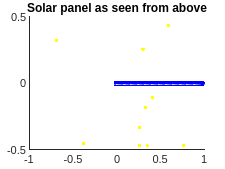

% Model the charged bar
Qbar = 7.44e-10; % C
barX = 0:0.01:L;
barY = 0;
barZ = 0.1; %m

% Plot the grains in the solar panel
figure
hold on
plot(sandX, sandY, '.y', 'MarkerSize', 5) % MarkerSize=1 for more grains
plot(barX, barY, '.b', 'MarkerSize', 10)
title('Solar panel as seen from above')
hold off

We then model the charged bars. They will do a circular movement, so they can be heuristically modeled as many points inside two disks

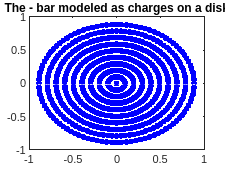

NCharges = 100;
theta=linspace(0, 2*pi - 2*pi/NCharges, NCharges);

nRings = 10;
ringsX=zeros(nRings, NCharges);
ringsY=zeros(nRings, NCharges);
ringsZ=barZ;
ring=1;
for i=0.1:0.1:0.9
    for j=1:NCharges
        ringsX(ring, j) = (L*i).*cos(theta(j));
        ringsY(ring, j) = (L*i).*sin(theta(j));
    end
    ring=ring+1;
end

plot(ringsX, ringsY, '.b', 'MarkerSize', 10)
title('The - bar modeled as charges on a disk')

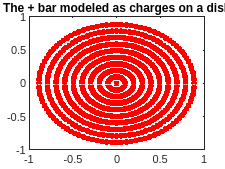

plot(ringsX, ringsY, '.r', 'MarkerSize', 10)
title('The + bar modeled as charges on a disk')

Calculate the electric force felt by each particle

SgFX=zeros(1, numGrains);
SgFY=zeros(1, numGrains);
SgFZ=zeros(1, numGrains);

for i=1:numGrains
    [Efnx, Efny, Efnz] = Efield3(ringsX, ringsY, ringsZ, sandX(i), sandY(i), sandZ, -Qbar);
    [Efpx, Efpy, Efpz] = Efield3(ringsX, ringsY, -ringsZ, sandX(i), sandY(i), sandZ, Qbar);
    
    Efx = Efpx + Efnx;
    Efy = Efpy + Efny;
    Efz = Efpz + Efnz;

    SgFX(i) = sum(Efx);
    SgFY(i) = sum(Efy);
    SgFZ(i) = sum(Efz);
end

SgFX;
SgFY;
SgFZ;

Plot the force for each particle in XZ plane

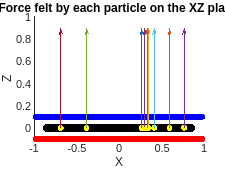

figure
hold on

mFXZ=zeros(1, numGrains);

for i=1:numGrains
    mFXZ(i)=sqrt(SgFX(i)^2 + SgFZ(i)^2);
end


plot(-barX(length(barX)):0.01:barX(length(barX)), barZ, '.b', 'MarkerSize', 10)
plot(-b/2:0.01:b/2, 0, '.k', 'MarkerSize', 15)
plot(-barX(length(barX)):0.01:barX(length(barX)), -barZ, '.r', 'MarkerSize', 10)
for i=1:numGrains
    plot(sandX(i), sandZ, '.y', 'MarkerSize', 10)
    xlabel('X')
    ylabel('Z')
    title("Force felt by each particle on the XZ plane")
    quiver(sandX(i), sandZ, SgFX(i)/mFXZ(i), SgFZ(i)/mFXZ(i))
end

hold off

Plot the force for each particle in YZ plane

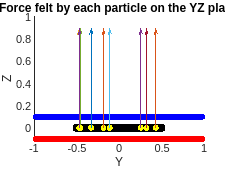

figure
hold on

mFYZ=zeros(1, numGrains);

for i=1:numGrains
    mFYZ(i)=sqrt(SgFY(i)^2 + SgFZ(i)^2);
end


plot(-barX(length(barX)):0.01:barX(length(barX)), barZ, '.b', 'MarkerSize', 10)
plot(-h/2:0.01:h/2, 0, '.k', 'MarkerSize', 15)
plot(-barX(length(barX)):0.01:barX(length(barX)), -barZ, '.r', 'MarkerSize', 10)
for i=1:numGrains
    plot(sandY(i), sandZ, '.y', 'MarkerSize', 10)
    xlabel('Y')
    ylabel('Z')
    title("Force felt by each particle on the YZ plane")
    quiver(sandY(i), sandZ, SgFY(i)/mFYZ(i), SgFZ(i)/mFYZ(i))
end
hold off

Model the system in 3D

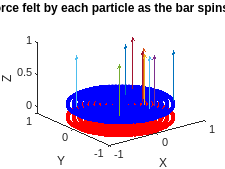

ringsZ=ones(nRings, NCharges)*ringsZ;

plot3(ringsX, ringsY, ringsZ,'.b')
hold on
plot3(ringsX, ringsY, -ringsZ,'.r')
hold off

hold on
sandZ = zeros(1, numGrains);
plot3(sandX, sandY, sandZ, '.y', 'MarkerSize', 0.01)

mFXYZ=zeros(1, numGrains);

for i=1:numGrains
    mFXYZ(i)=sqrt(SgFX(i)^2 + SgFY(i)^2 + SgFZ(i)^2);
end

for i=1:numGrains
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    title("Force felt by each particle as the bar spins (3D)")
    quiver3(sandX(i), sandY(i), sandZ(i), SgFX(i)/mFXYZ(i), SgFY(i)/mFXYZ(i), SgFZ(i)/mFXYZ(i))
end

We use Euler's method to numericaly calculate the velocity and position of sand particles across time

% v=zeros(3, numGrains); % xys velocity of each grain
% r=zeros(3, numGrains); % xyz position of each grain

ti=0;
tf=50;
n=1000; % number of values
h=(tf-ti)/n; % step
t=(ti:h:tf)';

vx=zeros(n, numGrains);
vy=zeros(n, numGrains);
vz=zeros(n, numGrains);

rx=zeros(n, numGrains);
ry=zeros(n, numGrains);
rz=ones(n, numGrains);

for i=1:numGrains
    rx(i, 1)=[sandX(i)];
    ry(i, 1)=[sandY(i)];
    rz(i, 1)=[sandZ(i)];
end

k = 1;
for i=1:numGrains
    while rz(k, i) <= barZ - 0.001
        [Efx, Efy, Efz] = Efield3(ringsX, ringsY, ringsZ, rx(i), ry(i), rz(i), -Qbar);
    
        % Add the force of gravity
        Fz = Efz - m*g;

        vz(k + 1, i) = vz(k, i)+h*(qG*sum(Fz)/m);
        rz(k + 1, i) = rz(k, i)+h*vz(k, i);
    
        k = k+1;
    end
    k = 1;
end

rz

rz =          0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.

We animate the motion of the sand particles

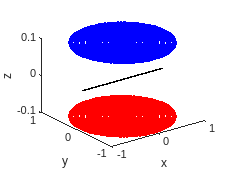

figure
plot3(ringsX,ringsY, ringsZ, '.b','MarkerSize', 10)
hold on
xlabel('x')
ylabel('y')
zlabel('z')

patch([-b/2, -b/2, b/2, b/2], [-h/2, h/2, h/2, -h/2], [0, 0, 0, 0], [0.3, 0.3, 0.3])
plot3(ringsX,ringsY, -ringsZ, '.r','MarkerSize',10)
electron=plot3(rx(:,1),ry(:,1), rz(1:n, 1), '.k','MarkerSize',30);
for i=1:10:n
    delete(electron);
    electron=plot3(rx(i,1),ry(i,1), rz(i, 1), '.k','MarkerSize',30);
    xlim([-1,1])
    ylim([-1,1])
    zlim([-0.1,0.1])
    drawnow;
end